 
close all
clear all
clc


fileID = fopen('wall_seg1.txt','r');
tline = fgetl(fileID)

tline = 'Sample Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

size1 = fgetl(fileID)

size1 = '5267'

tline = fgetl(fileID)

tline = 'Data:'

formatSpec = '%d';
roi_index_wall1 = fscanf(fileID,formatSpec)

roi_index_wall1 =    225
   226
   227
   228
   229
   230
   231
   232
   233
   234


tline = fgetl(fileID)

tline = 'Coefficient of the plane:'

tline = fgetl(fileID)

tline = '-0.912561 0.399315 0.088205 21.080698'

tline = fgetl(fileID)

tline = 'Inliers Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

tline = fgetl(fileID)

tline = '5267'

tline = fgetl(fileID)

tline = 'Data:'

plane_index_wall1 = fscanf(fileID,formatSpec)

plane_index_wall1 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


fclose(fileID);


fileID = fopen('wall_seg2.txt','r');
tline = fgetl(fileID)

tline = 'Sample Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

size1 = fgetl(fileID)

size1 = '8212'

tline = fgetl(fileID)

tline = 'Data:'

formatSpec = '%d';
roi_index_wall2 = fscanf(fileID,formatSpec)

roi_index_wall2 =    281
   282
   283
   284
   285
   286
   287
   288
   289
   290


tline = fgetl(fileID)

tline = 'Coefficient of the plane:'

tline = fgetl(fileID)

tline = '0.015617 -0.005867 0.999861 -6.359678'

tline = fgetl(fileID)

tline = 'Inliers Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

tline = fgetl(fileID)

tline = '8212'

tline = fgetl(fileID)

tline = 'Data:'

plane_index_wall2 = fscanf(fileID,formatSpec)

plane_index_wall2 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


fclose(fileID);

fileID = fopen('wall_seg4.txt','r');
tline = fgetl(fileID)

tline = 'Sample Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

size1 = fgetl(fileID)

size1 = '445'

tline = fgetl(fileID)

tline = 'Data:'

formatSpec = '%d';
roi_index_wall4 = fscanf(fileID,formatSpec)

roi_index_wall4 =        63364
       63727
       63728
       64090
       64091
       64092
       64093
       64453
       64454
       64455


tline = fgetl(fileID)

tline = 'Coefficient of the plane:'

tline = fgetl(fileID)

tline = '0.010469 -0.007190 0.999919 -10.692945'

tline = fgetl(fileID)

tline = 'Inliers Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

tline = fgetl(fileID)

tline = '445'

tline = fgetl(fileID)

tline = 'Data:'

plane_index_wall4 = fscanf(fileID,formatSpec)

plane_index_wall4 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


fclose(fileID);

fileID = fopen('ground_seg3.txt','r');
tline = fgetl(fileID)

tline = 'Sample Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

size1 = fgetl(fileID)

size1 = '24985'

tline = fgetl(fileID)

tline = 'Data:'

formatSpec = '%d';
roi_index_ground_seg3 = fscanf(fileID,formatSpec)

roi_index_ground_seg3 =        68973
       69330
       69331
       69332
       69333
       69689
       69690
       69691
       69692
       69693


tline = fgetl(fileID)

tline = 'Coefficient of the plane:'

tline = fgetl(fileID)

tline = '-0.000107 0.098099 0.995177 -0.087079'

tline = fgetl(fileID)

tline = 'Inliers Indices'

tline = fgetl(fileID)

tline = 'Indices Size:'

tline = fgetl(fileID)

tline = '15769'

tline = fgetl(fileID)

tline = 'Data:'

plane_index_ground_seg3 = fscanf(fileID,formatSpec)

plane_index_ground_seg3 =      6
    15
    20
    21
    23
    24
    25
    30
    31
    32


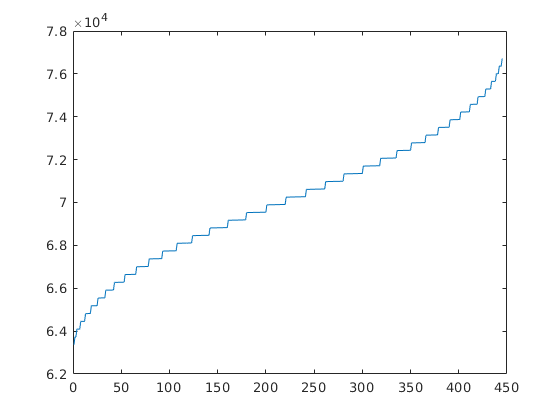

fclose(fileID);

figure
plot(roi_index_wall4)

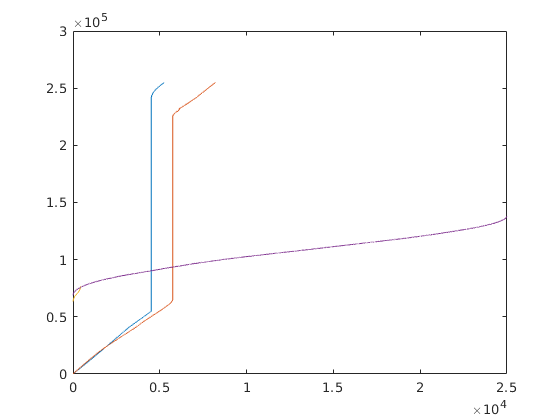


figure
plot(roi_index_wall1)
hold on
plot(roi_index_wall2)
hold on
plot(roi_index_wall4)
hold on
plot(roi_index_ground_seg3)

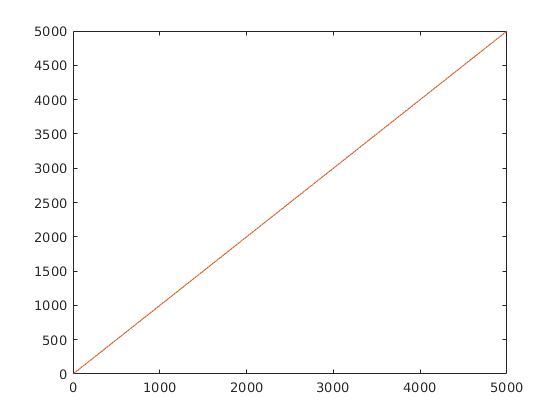



figure
plot(plane_index_wall1(1:5000))
hold on
plot(plane_index_wall2(1:5000))
hold on

plot(plane_index_wall4(1:5000))

Index exceeds the number of array elements (445).

hold on
plot(plane_index_ground_seg3(1:5000))

figure
plot(roi_index_wall1)

inputCloud = pcread(['low_pitch_angle_slow_speed_right_turn1.pcd']);
filteredCloud = removeInvalidPoints(inputCloud);
% sampleIndices = findPointsInROI(filteredCloud,roi);
% sIndicesSorted = sort(sampleIndices);
roi_cloud = select(filteredCloud,roi_index_wall1);
figure
pcshow(roi_cloud)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('roi cloud')

roi_cloud = select(filteredCloud,roi_index_wall2);
figure
pcshow(roi_cloud)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('roi cloud')

wall_seg_cloud4 = pcread(['wall_seg_cloud4.pcd']);

figure
plot(roi_index_wall1, 'g')



